%Testing Time Input. See P4 for non-time input.
clc
clear;

%%%%%%SELECT OPTIONS:
problem_num = 1;
diff_opt = "forward"; %{forward, backward, centered}
partition_opt = "full"; %{full, partition}

%%%%%%SET UP NEURAL NETWORK
occurences = 1000;

%(1) Set up initial conditions and solve ODE:
function [C, t, h, arraySize, num_outputs] = probsetup(problem_num, occurences)
    if problem_num == 1
        c0 = [4.0; 1.0; 0.5; 0.0]; %initial condition
        tspan = linspace(0, 2, occurences); %constant time step
        h = 2/occurences;
        arraySize = [48 24 12 3];
        num_outputs = 4;
        
        k1 = 5.7; k2 = 6.1; 
        dCdt = @(t, C) [ %setup ODE
            -k1 * C(1)
             k2 * C(1) - k2 * C(2)
             k2 * C(2)
             k1 * C(1) + k2 * C(2)
        ];
    elseif problem_num == 2
        c0 = [10.0; 5.0; 1.0]; %initial condition
        tspan = linspace(0, 1, occurences);
        h = 1/occurences;
        arraySize = [120 40 18 9];
        num_outputs = 3;

        dCdt = @(t, C) [
            (C(1) + 0.25) - sin(C(3))
            0.5 - C(2) * cos(C(1))
            C(1)^2 + sin(C(3))
        ];
    elseif problem_num == 3
        c0 = [4.0; 1.0; 0.5; 0.0]; %initial condition
        tspan = linspace(0, 2, occurences); %constant time step
        h = 2/occurences;
        arraySize = [24 12];
        num_outputs = 4;
        
        k1 = 5.7; k2 = 6.1; 
        dCdt = @(t, C) [ %setup ODE
            -k1 * C(1) * t
             k2 * C(1) * t - k2 * C(2) * t
             k2 * C(2) * t
             k1 * C(1) * t + k2 * C(2) * t
        ];        
    elseif problem_num == 4
        %Answer: C(t) = c0 * e^(3t)     for dC/dt = 3C(1) + 0*t, c0=c0
        %Answer: C(t) = 3t + c0         for dC/dt = 3, c0=c0
        %Answer: C(t) = 0               for dC/dt = 3C(1), c0 = 0
        c0 = [0.0];
        tspan = linspace(0, 1, occurences); 
        h = 1/occurences;
        arraySize = [2 4];
        num_outputs = 1;

        dCdt = @(t, C)[
            %3*C(1) + 0*t       
            %3 + 0*C(1) + 0*t
            3*C(1)
         ];
    end %if 
    [t, C] = ode45(dCdt, tspan, c0); %solve ODE
end %function 

%(2) Calculate dX/dt
function [Xout, dXdt, dt] = diffmethod(Xin, t, h, diff_opt)
    if diff_opt == "forward"
        dXdt = (Xin(2:end,:) - Xin(1:end-1,:))/h; 
        Xout = [Xin(1:end-1,:) t(1:end-1)];         %Edited forward pass only.
        %Xout = Xin(1:end-1, :);
        dt = t(2:end) - t(1:end-1);
    end %if 
end %function 

%(3) Train model to map (x, t) -> dx/dt
function [modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)
    rng("default") 
    c = cvpartition(length(Y),"Holdout",0.20);
    trainingIdx = training(c); 
    XTrain = X(trainingIdx,:);
    YTrain = Y(trainingIdx,:);
    testIdx = test(c);
    XTest = X(testIdx,:);
    YTest = Y(testIdx,:);
    
    if partition_opt == "full"
        modelNN2 = fitrnet(X,Y,"Standardize",true, ...
            "LayerSizes", arraySize); %TODO: false
    elseif partition_opt == "partition"
        modelNN2 = fitrnet(XTrain,YTrain,"Standardize",false, ...
            "LayerSizes", arraySize);    
    end %if 
    lossNN2 = loss(modelNN2, XTest, YTest);
end %function 

[C, t, h, arraySize, num_outputs] = probsetup(problem_num, occurences);
[X, Y, dt] = diffmethod(C, t, h, diff_opt);
[modelNN2, lossNN2] = trainNN(X, Y, arraySize, partition_opt)

modelNN2 =   RegressionNeuralNetwork
             ResponseName: {'y1'  'y2'  'y3'  'y4'}
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 999
               LayerSizes: [48 24 12 3]
              Activations: 'relu'
    OutputLayerActivation: 'none'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods


lossNN2 = 1.3573e-05

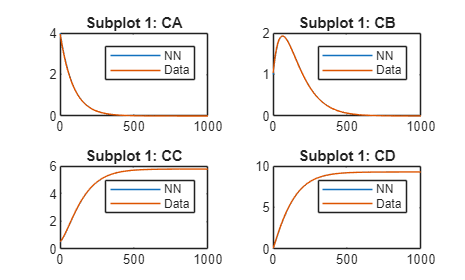


%%%%%%RESULT VALIDATION: Explicit Euler:
%(1) Calculate f'(x, t) using NN
% Assume t updates appropriately.
fNN = zeros(occurences-1, num_outputs);
fNN(1:3, :) = C(1:3, :); 
for i = 2:(occurences-2)
    fNN(i+1,:) = fNN(i,:) + dt(i) .* predict(modelNN2, [fNN(i,:) t(i)]);
    %fNN(i+1,:) = fNN(i,:) + dt(i) .* predict(modelNN2, [fNN(i,:)]);
end %for

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

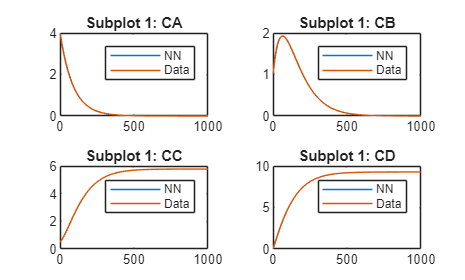

%%%%%%RESULT VALIDATION: FORWARD PASS:
%(1) Calculate f'(x) using NN
fNN = zeros(occurences-1, num_outputs);
fNN(1, :) = C(1, :);
numLayers = size(arraySize, 2);
for i = 1:(occurences-1)
    zk = [fNN(i, :)'; t(i)]; %update with time 
    zk = (zk - modelNN2.Mu') ./ modelNN2.Sigma'; %TODO: remove
    %zk = [fNN(i, :)']; %update without time variable
    for j = 1:numLayers
        zk = modelNN2.LayerWeights{j} * zk + modelNN2.LayerBiases{j};
        zk = max(0, zk);
    end %for
    zk = modelNN2.LayerWeights{numLayers+1} * zk + modelNN2.LayerBiases{numLayers+1}; 
   
    fNN(i+1, :) = fNN(i, :) + dt(i) .* zk';
end %for 

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

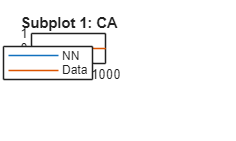

fNN = zeros(occurences-1, num_outputs);
fNN(1, :) = C(1, :);
numLayers = size(arraySize, 2);

for i = 1:(occurences-1)
    zk = [fNN(i, :)']; %update without time variable
    for j = 1:numLayers
        if j == 1
            timeinput = modelNN2.LayerWeights{j}(:, end) * t(i);
            zk = modelNN2.LayerWeights{j}(:, 1:end-1) * zk + modelNN2.LayerBiases{j} + timeinput;
        else
            zk = modelNN2.LayerWeights{j} * zk + modelNN2.LayerBiases{j};
        end %if 
        zk = max(0, zk);
    end %for
    zk = modelNN2.LayerWeights{numLayers+1} * zk + modelNN2.LayerBiases{numLayers+1};
    
    fNN(i+1, :) = fNN(i, :) + dt(i) .* zk';
end %for 

%(2) Plot to check results (Raw data vs NN)
figure
hold on
p = tiledlayout(2,2);
ptitles = ['Subplot 1: CA'
    'Subplot 1: CB'
    'Subplot 1: CC'  
    'Subplot 1: CD'];
for i = 1:num_outputs
    nexttile;
    plot([fNN(1:(occurences-1),i), C(2:occurences,i)])
    legend('NN', 'Data')
    title(ptitles(i, :))
end 
hold off

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(C, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')

%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    writematrix(modelNN2.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
end %for 

filename = "FitRNet_Storage_THETA.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    if i == 1
        A = modelNN2.LayerWeights{1} ./ modelNN2.Sigma
        writematrix(A, filename,'Sheet', i, 'Range', 'A1')
    else 
        writematrix(modelNN2.LayerWeights{i}, filename,'Sheet', i, 'Range', 'A1')
    end 
end %for 

A =     0.4684    0.0108   -0.0857    0.0619    0.2591
   -0.0227   -0.6574   -0.0492    0.0510   -0.0505
   -0.0922    0.5002   -0.2314    0.1010    0.2580
    0.3095    0.5117   -0.0476   -0.0792   -0.6939
   -0.1056   -0.2475    0.0197   -0.0912    0.3242
    0.0980    0.8459    0.0748    0.1137   -0.5309
    0.1221   -0.4409    0.0687    0.1177   -0.0180
   -0.1511    0.2655   -0.2373    0.0763   -0.3023
   -0.3118    0.3265    0.1638    0.0352    0.2260
   -0.3496    0.1895    0.1534   -0.0814   -0.1861
   -0.0685    0.3379    0.1492    0.1453    0.1247
   -0.0074    0.6774   -0.3658   -0.2137    0.1635
    0.3965    0.0696   -0.1124    0.0254   -0.3745
   -0.0846   -0.3740    0.0869    0.0371   -0.0688
    0.3670   -0.1940    0.0675    0.0782    0.5343


filename = "FitRNet_Storage_CCOEFF.xlsx";
for i = 1:length(modelNN2.LayerSizes)+1
    if i == 1
        A = modelNN2.LayerBiases{1} - (modelNN2.LayerWeights{1} * (modelNN2.Mu ./ modelNN2.Sigma)');
        writematrix(A, filename,'Sheet', i, 'Range', 'A1');
    else 
        writematrix(modelNN2.LayerBiases{i}, filename,'Sheet', i, 'Range', 'A1')
    end 
end %for 